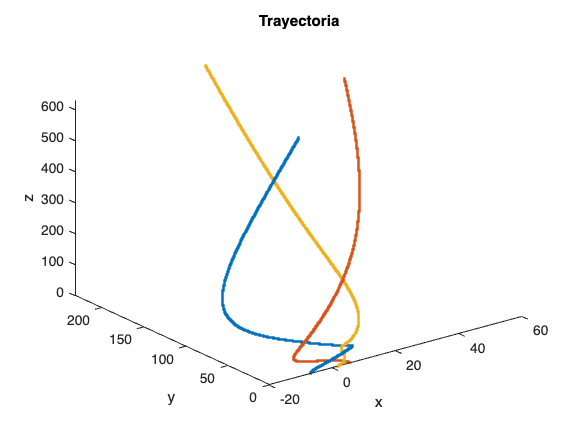

clear; close all; clc


%astronomical units constants
G=0.01720209895;
%we will work with three planets, m1 has 1 solar mass so it can be
%considered as the sun, and m2, m3 have 1.5 and 2 times the mass o the sun
%respectively.
m1=1;
m2=1.5;
m3=2;

%time step
tf=365*11;
dt=.5;
t=0:dt:tf;


%vector of masses
m=[m1,m2,m3];

%we are working with astronomical units, so time will be days, distance
%will be AUs, and velocity will be AU/day
%condiciones para puntos 1-6
%initial condition of m1 (blue trajectory)
R1=zeros(length(t),3);
v1=zeros(length(t),3);
R1(1,:)=[-6.5,1,0];
v1(1,:)=[0.0,0,0.15];
%initial condition of m2 (red trajectory)
R2=zeros(length(t),3);
v2=zeros(length(t),3);
R2(1,:)=[5.7,0,0];
v2(1,:)=[0,0.1,0.15];
%initial condition of m3 (yellow trajectory)
R3=zeros(length(t),3);
v3=zeros(length(t),3);
R3(1,:)=[1.5,0,0];
v3(1,:)=[0,0,0.025];

%total mechanic energy initial condition
Etot(1)=0;
for i=1:length(t)-1
    %we calculate the time base in the time step
    ti(i+1)=t(i)+dt;
    a1=G*(m(2)*(R2(i,:)-R1(i,:))/(norm(R2(i,:)-R1(i,:)))^3+m(3)*(R3(i,:)-R1(i,:))/(norm(R3(i,:)-R1(i,:)))^3);
    a2=G*(m(1)*(R1(i,:)-R2(i,:))/(norm(R1(i,:)-R2(i,:)))^3+m(3)*(R3(i,:)-R2(i,:))/(norm(R3(i,:)-R2(i,:)))^3);
    a3=G*(m(1)*(R1(i,:)-R3(i,:))/(norm(R1(i,:)-R3(i,:)))^3+m(2)*(R2(i,:)-R3(1,:))/(norm(R2(i,:)-R3(i,:)))^3);

    v1(2*i,:)=v1(2*i-1,:)+.5*a1*dt;
    v2(2*i,:)=v2(2*i-1,:)+.5*a2*dt;
    v3(2*i,:)=v3(2*i-1,:)+.5*a3*dt;

    R1(i+1,:)=R1(i,:)+v1(2*i,:)*dt;
    R2(i+1,:)=R2(i,:)+v2(2*i,:)*dt;
    R3(i+1,:)=R3(i,:)+v3(2*i,:)*dt;

    a1=G*(m(2)*(R2(i+1,:)-R1(i+1,:))/(norm(R2(i+1,:)-R1(i+1,:)))^3+m(3)*(R3(i+1,:)-R1(i+1,:))/(norm(R3(i+1,:)-R1(i+1,:)))^3);
    a2=G*(m(1)*(R1(i+1,:)-R2(i+1,:))/(norm(R1(i+1,:)-R2(i+1,:)))^3+m(3)*(R3(i+1,:)-R2(i+1,:))/(norm(R3(i+1,:)-R2(i+1,:)))^3);
    a3=G*(m(1)*(R1(i+1,:)-R3(i+1,:))/(norm(R1(i+1,:)-R3(i+1,:)))^3+m(2)*(R2(i+1,:)-R3(i+1,:))/(norm(R2(i+1,:)-R3(i+1,:)))^3);

    v1(2*i+1,:)=v1(2*i,:)+.5*a1*dt;
    v2(2*i+1,:)=v2(2*i,:)+.5*a2*dt;
    v3(2*i+1,:)=v3(2*i,:)+.5*a3*dt;

    %it's possible to calculate the distance between objects
    %m1-m2
    d1=abs(norm(R2(i)-R1(i)));
     %m1-m3
    d2=abs(norm(R3(i)-R1(i)));
     %m2-m3
    d3=abs(norm(R3(i)-R2(i)));

    %Calculate total mechanic energy

    K=(0.5.*m1.*((v1(i)).^2))+(0.5.*m2.*((v2(i)).^2))+(0.5.*m3.*((v3(i)).^2));
    U=(G.*((m1.*m2)./d1))+(G.*((m2.*m3)./d3))+(G.*((m1.*m3)./d2));

    Etot(i+1)=K+U;
    
    %animation, uncomment this section 
%     plot3(R1(:,1),R1(:,2),R1(:,3),'.',R2(:,1),R2(:,2),R2(:,3),'.',R3(:,1),R3(:,2),R3(:,3),".");
%     drawnow
end
% 
p = plot3(R1(:,1),R1(:,2),R1(:,3),'.',R2(:,1),R2(:,2),R2(:,3),'.',R3(:,1),R3(:,2),R3(:,3),".");
xlabel('x'); ylabel('y'); zlabel('z'); 
title("Trayectoria")

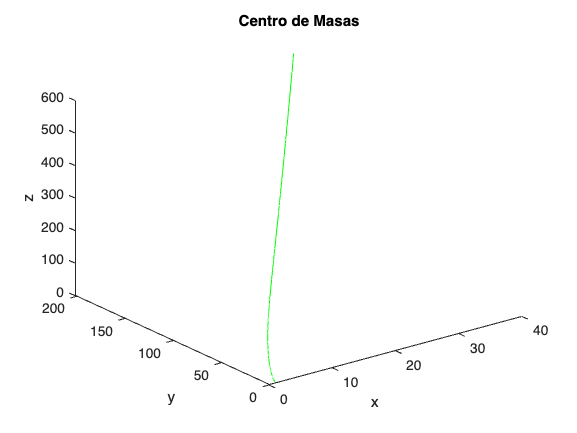

%we can plot the barycenter
barycenter = (m1*R1 + m2*R2 + m3*R3) / (m1+m2+m3);
plot3(barycenter(:, 1), barycenter(:, 2), barycenter(:, 3), '-g')
xlabel('x'); ylabel('y'); zlabel('z');
title("Centro de Masas")

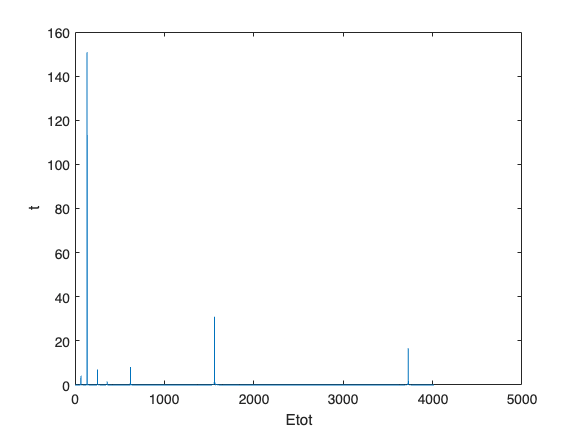

%we can plot the total energy
plot(ti,Etot)
xlabel('Etot'); ylabel('t')